mea_max = measure_white(ol,cs);

Yxy =    57.6280    0.3789    0.4098



mea_min = measure_black(ol,cs);

Yxy =     0.0389    0.4039    0.4113


load('runme_data','M','B')

d65 = B;

spd_target_orig = d65;

% spd_0 = ls.spd_0';
% spd_max = ls.spd_all' - spd_0;
mea_max = measure_white(ol,cs);

Yxy =    60.8100    0.3781    0.4093


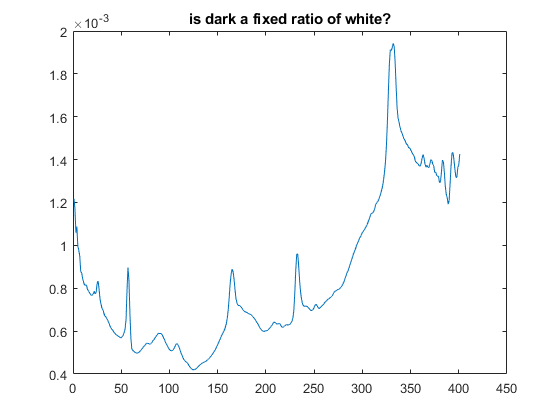


spd_0 = mea_min.amplitude';
spd_max = mea_max.amplitude';

ratio_0 = spd_0 ./ spd_max;

clf
plot(ratio_0)
title('is dark a fixed ratio of white?')

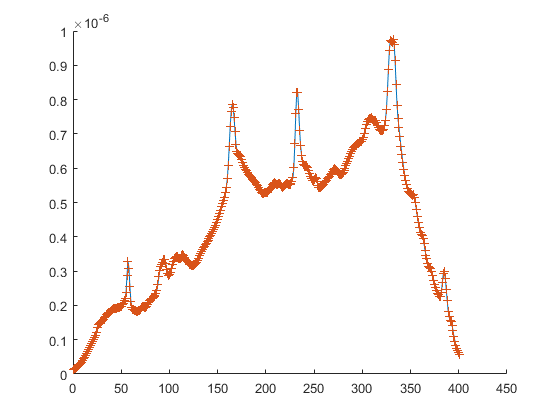


clf
hold on
plot(spd_0)
plot(spd_max .*  ratio_0,'+')


sc = 0.1

sc = 0.1000

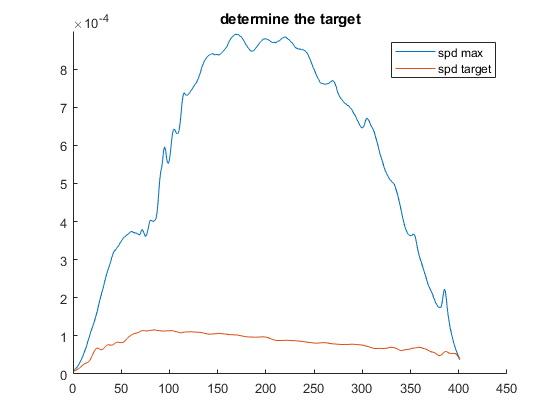

spd_target = spd_target_orig .* sc;
clf
hold on
plot(spd_max)
plot(spd_target)
legend('spd max','spd target')
title('determine the target')

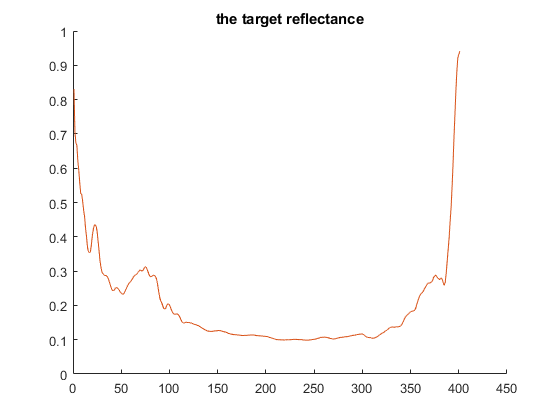

ref_target_orig = (spd_target - spd_0) ./ (spd_max - spd_0);
ref_target = min(1,ref_target_orig);

clf
hold on
plot(ref_target_orig)
plot(ref_target)
title('the target reflectance')

ref_m = ls.reflectance';

vec_a_orig = R_callRsolver1024(ref_m,ref_target);

ans = 'Solving M * A = B with R...'

ans = 0

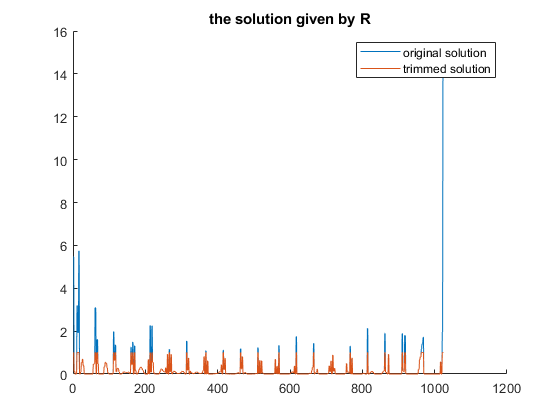

vec_a = vec_a_orig;
vec_a = min(1,vec_a);
vec_a = max(0,vec_a);

clf
hold on
plot(vec_a_orig)
plot(vec_a)
legend('original solution','trimmed solution')
title('the solution given by R')

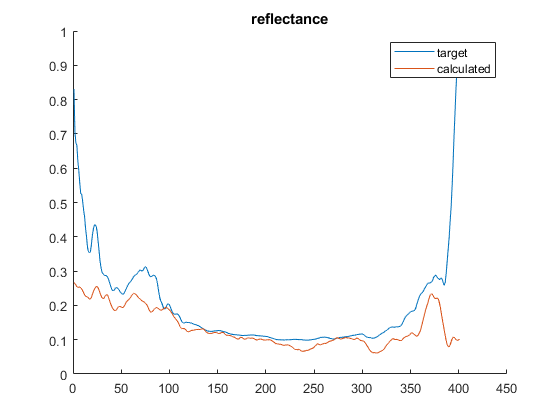

clf
hold on
plot(ref_target)
ref = ref_m * vec_a;
plot(ref)
legend('target','calculated')
title('reflectance')

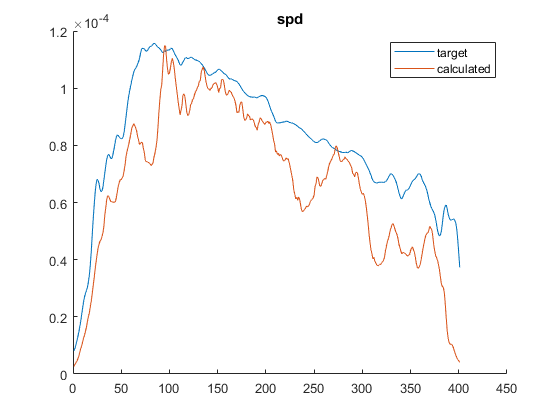

clf
hold on
plot(spd_target)
spd = spd_max .* ref + spd_0;
plot(spd)
legend('target','calculated')
title('spd')

the vec needs to be doubled to match

spec_predicted = ls.predict_vec_max(vec_a,spd_max);

ol.setColumn1024Gamma(vec_a)
mea = cs.measure;

Yxy =     5.2710    0.3130    0.3540


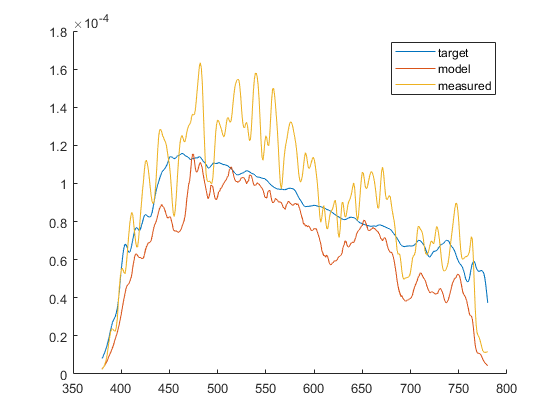

t = mea.amplitude;

clf
hold on

spd_target_ref = spd_max .* ref_target + spd_0;
plot(380:780,spd_target_ref)

plot(380:780,spec_predicted)

%spd = spd_max .* ref + spd_0;
%plot(380:780,spd)

%mea.plot
plot(380:780,t/0.6)
legend('target','model','measured')

%clf
%plot(t,)

ol.setColumn1024(LightSim.multiple_peaks(1:1024))
mea_all = cs.measure;

Yxy =    52.8380    0.3752    0.4089


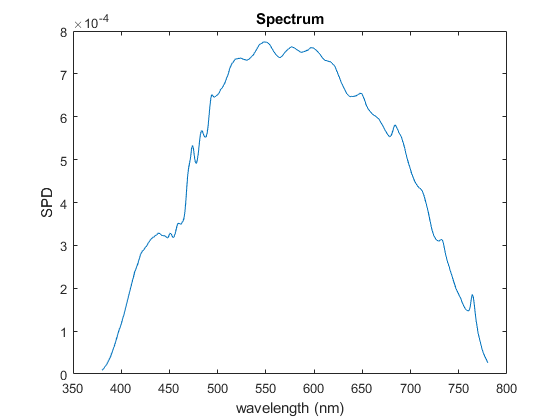

clf
mea_all.plot

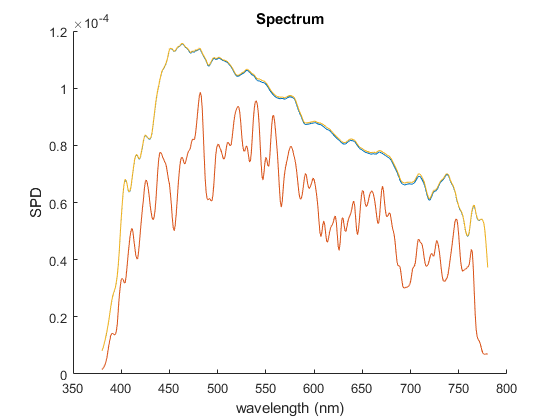

clf
hold on
plot(380:780,spd_max .* ref_target)
mea.plot
plot(380:780,spd_target)

%plot(380:780,spd_max)
%mea_all.plot

c_range = [1:100:1000];

ol.setColumn1024(LightSim.multiple_peaks(c_range))
mea_500 = cs.measure;

Yxy =     0.6520    0.3836    0.4149



ol.setColumn1024(LightSim.multiple_peaks([1:1024]))
mea_all = cs.measure;

Yxy =    61.4430    0.3782    0.4093



s_pred = ls.predict_by_filter(LightSim.multiple_peaks(c_range));

Unrecognized method, property, or field 'predict_by_filter' for class 'LightSim'.


clf
hold on
t_500 = mea_500.amplitude ./ mea_all.amplitude;
%plot(t_500)
mea_500.plot
plot(380:780,s_pred)

col_g = 435

col_g = 435

col_width = 140;
c_range = [col_g-col_width:col_g+col_width];
x_g = 0.33;
y_g = 0.6;
[100 x_g y_g atan2d(y_g,x_g) (x_g.^2+y_g.^2).^0.5]

ans =   100.0000    0.3300    0.6000   61.1892    0.6848



ol.setColumn1024(LightSim.multiple_peaks(c_range))
Yxy = cs.measure_Yxy

Yxy =    43.4120    0.3350    0.5956   60.6441    0.6833


col_r = 730

col_r = 730

col_width = 150;
c_range = [col_r-col_width:col_r+col_width];
x_r = 0.64;
y_r = 0.30;
[100 x_r y_r atan2d(y_r,x_r) (x_r.^2+y_r.^2).^0.5]

ans =   100.0000    0.6400    0.3000   25.1148    0.7068



ol.setColumn1024(LightSim.multiple_peaks(c_range))
Yxy = cs.measure_Yxy

Yxy =     9.8866    0.6792    0.3200   25.2271    0.7508


return

clf
hold on
mea_500.plot

how wide need to reach max

c_range = 1:1024;
vec = LightSim.multiple_peaks(c_range);
ol.setColumn1024(vec)
mea_max = cs.measure;

Yxy =    53.5860    0.3749    0.4088




width = 25;
wl = 708;
c_range = [wl-width:wl+width];
vec = LightSim.multiple_peaks(c_range);
ol.setColumn1024(vec)
mea = cs.measure;

Yxy =     1.0616    0.7150    0.2812


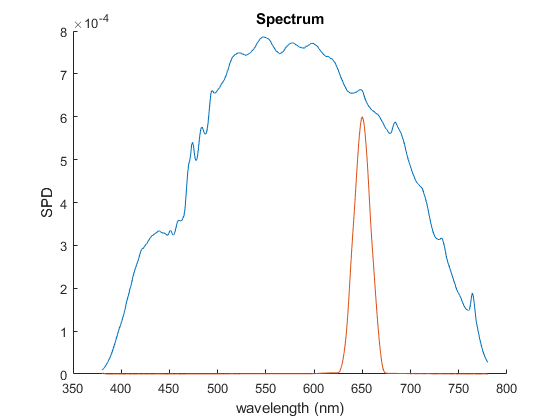

clf
hold on
mea_max.plot
mea.plot

vec8_array = ls.vec_8_spikes;
vec8_sum = sum(vec8_array,1);

ol.setColumn1024(vec8_sum)
mea_8 = cs.measure;

Yxy =    20.5890    0.3816    0.4083


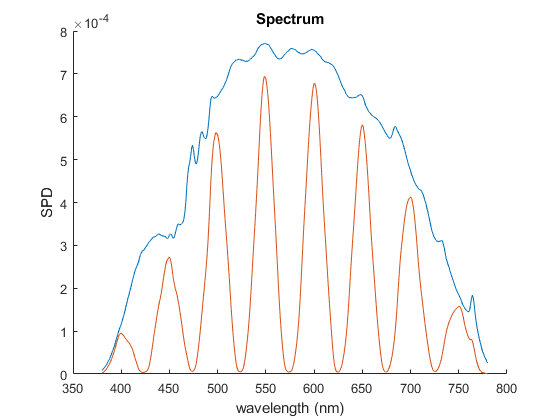


clf
hold on
mea_max.plot
mea_8.plot

i=5;
ol.setColumn1024(vec8_array(i,:))
mea = cs.measure;

Yxy =     6.6957    0.6193    0.3792


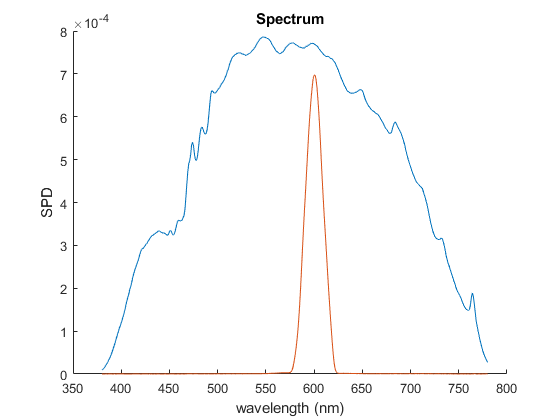

clf
hold on
mea_max.plot
mea.plot

spd_target

spd_target = 	1.0e+-3 *

    0.0204
    0.0223
    0.0255
    0.0287
    0.0325
    0.0364
    0.0413
    0.0461
    0.0520
    0.0578


index_8 = wl_center - 380 + 1;
amp_8_target = spd_target(index_8)';
amp_8_max = mea_8.amplitude(index_8);
ratio_8 = amp_8_target ./ amp_8_max;
ratiovec_8 = interp1(veclut(:,2),veclut(:,1),ratio_8,'spline')

ratiovec_8 =     0.8562    1.0020    0.7427    0.6780    0.6513    0.6598    0.6980    0.9679


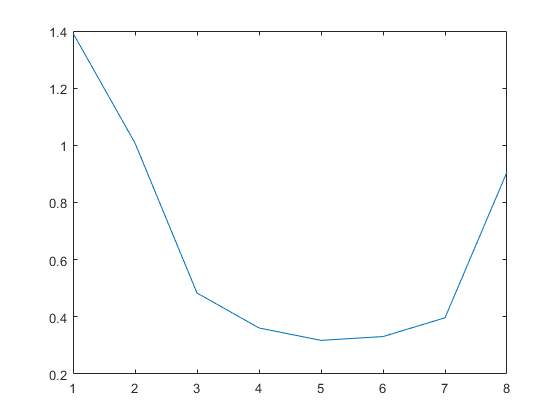

%ratio_8 = [1 1 1 1 1 1 1 1] * 0.8;

clf
plot(ratio_8)


vec = vec8_array' * ratio_8';
ol.setColumn1024(vec)
mea = cs.measure;

Yxy =     7.2211    0.2989    0.3066


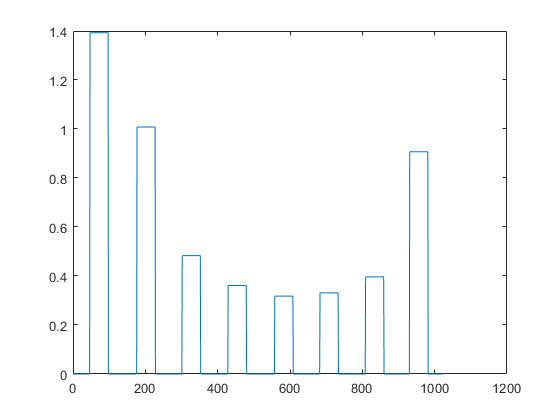

clf
plot(vec)

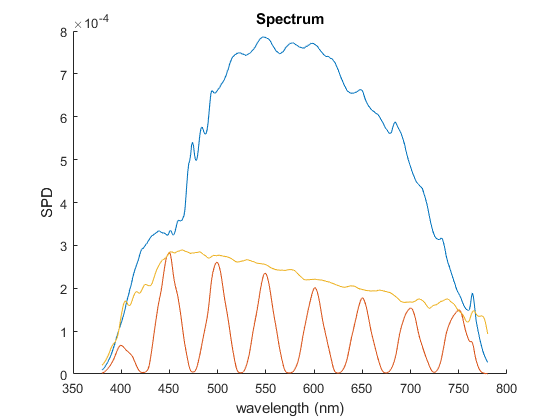


clf
hold on
mea_max.plot
mea.plot
plot(380:780,spd_target)

for i = 1:10
    ratio_8 = [1 1 1 1 1 1 1 1] * i / 10;
    vec = vec8_array' * ratio_8';
    ol.setColumn1024(vec)
    mea = cs.measure;
    meascale{i} = mea;
end

Yxy =     0.0889    0.3963    0.4161


Yxy =     0.2397    0.3858    0.4146


Yxy =     0.5078    0.3855    0.4128


Yxy =     0.9330    0.3753    0.4059


Yxy =     2.1861    0.3826    0.4111


Yxy =     4.2601    0.3787    0.4089


Yxy =     7.3641    0.3798    0.4089


Yxy =    11.1760    0.3804    0.4091


Yxy =    15.1500    0.3805    0.4086


Yxy =    19.9380    0.3818    0.4083


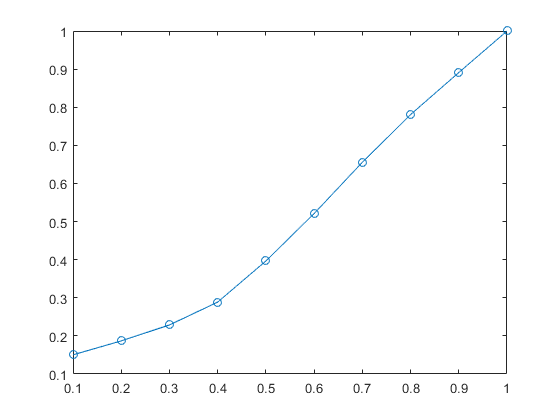


r = zeros(8,401);
for i = 1:10
    r(i,:) = meascale{i}.amplitude ./ meascale{10}.amplitude;
end
rmean = mean(r,2);
%veclut = [[0.1:0.1:1]' rmean]
%save('veclut','veclut')
clf
plot(0.1:0.1:1,rmean.^(1/2.2),'o-')

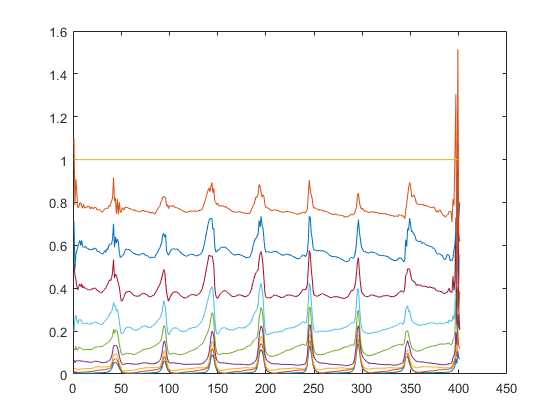



clf
plot(r')

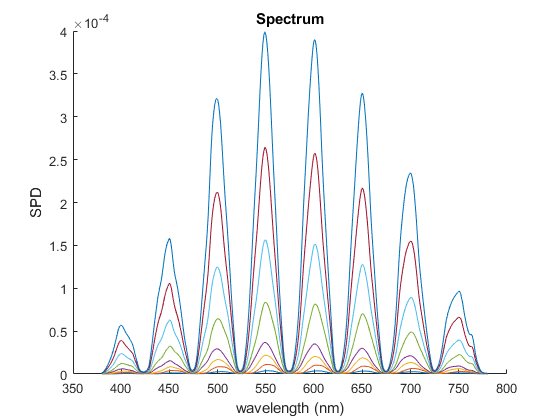


clf
hold on
for i = 1:8
    meascale{i}.plot
end

ratio_spec = zeros(10,401);
col_range  = [1:1024];
for i = 1:10
    rat = i/10;
    vec = LightSim.multiple_peaks(col_range) * rat;
    ol.setColumn1024(vec)
    mea = cs.measure;
    ratio_spec(i,:) = mea.amplitude;
end

Yxy =     0.1223    0.3846    0.4063


Yxy =     0.3639    0.3695    0.4027


Yxy =     0.8948    0.3716    0.4037


Yxy =     1.8303    0.3606    0.3981


Yxy =     4.8629    0.3724    0.4056


Yxy =    10.0310    0.3704    0.4056


Yxy =    18.1650    0.3726    0.4073


Yxy =    30.2430    0.3758    0.4089


Yxy =    44.8340    0.3772    0.4094


Yxy =    61.2670    0.3781    0.4092


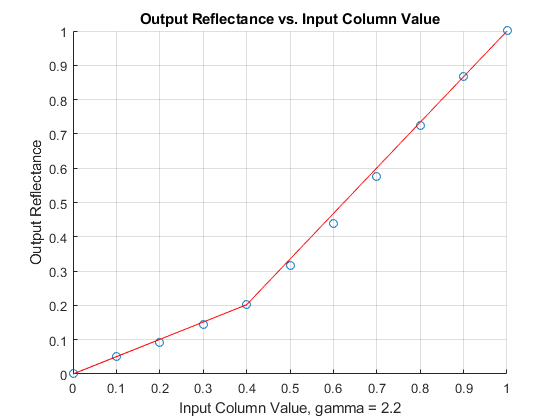

ratio_max = repmat(ratio_spec(10,:),10,1);
ratio_min = repmat(mea_min.amplitude,10,1);
ratio_spec_normal = (ratio_spec - ratio_min) ./ (ratio_max - ratio_min);
ratio_spec_normal_mean = mean(ratio_spec_normal(:,50:end-50)');

gamma_lut = [[0:0.1:1]' [0 ratio_spec_normal_mean]'];
save('gamma_lut','gamma_lut')

clf
hold on
x = gamma_lut(:,1);
y = gamma_lut(:,2);
plot(x,y.^(1/2.2),'o')
knee = 5;
plot(x([1 knee]),y([1 knee]).^(1/2.2),'-r')
plot(x([knee 11]),y([knee 11]).^(1/2.2),'-r')
grid on
axis([0 1 0 1])
xlabel('Input Column Value, gamma = 2.2')
ylabel('Output Reflectance')
title('Output Reflectance vs. Input Column Value')

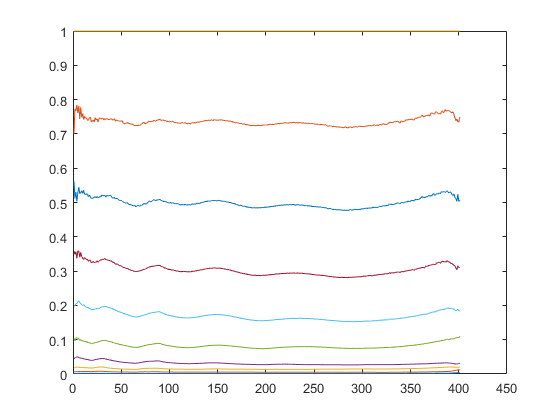



clf
plot(ratio_spec_normal(:,:)')

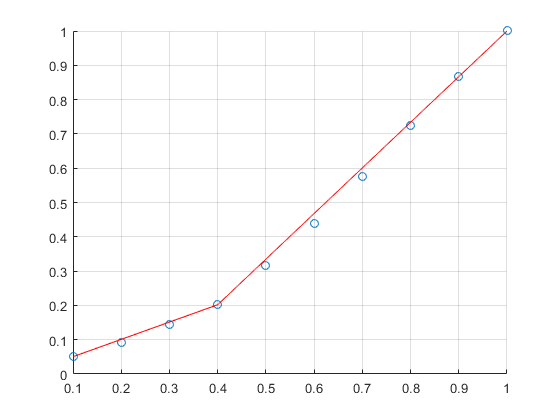


clf
hold on
x = 0.1:0.1:1;
y = mean(ratio_spec_normal(:,50:end-50)');
plot(x,y.^(1/2.2),'o')
%axis([0 1 0 1])
plot(x([1 4]),y([1 4]).^(1/2.2),'-r')
plot(x([4 10]),y([4 10]).^(1/2.2),'-r')
grid on

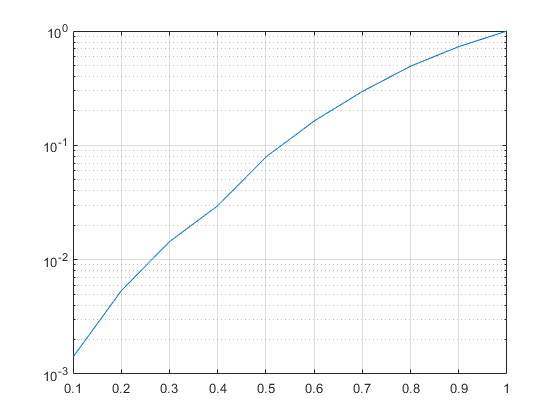


clf
semilogy(x,y)
grid on


slope = mean((y(2:end)-y(1:end-1))./(x(2:end)-x(1:end-1)))

slope = 1.1095

perc = y ./ x

perc =     0.0141    0.0267    0.0479    0.0740    0.1581    0.2721    0.4228    0.6156    0.8117    1.0000


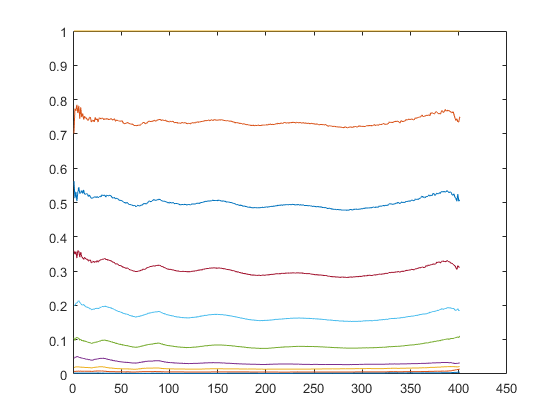

ratio_spec_normal = ratio_spec ./ repmat(ratio_spec(10,:),10,1);

clf
plot(ratio_spec_normal(:,:)')

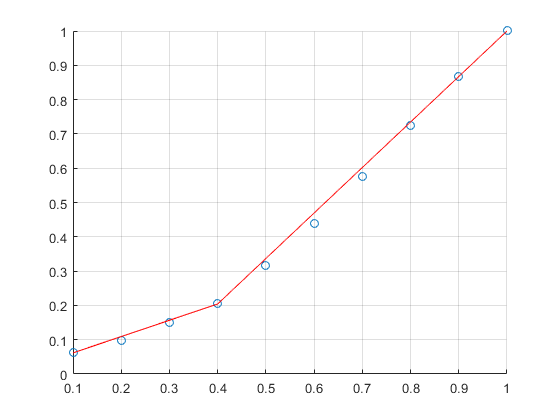


clf
hold on
x = 0.1:0.1:1;
y = mean(ratio_spec_normal(:,50:end-50)');
plot(x,y.^(1/2.2),'o')
%axis([0 1 0 1])
plot(x([1 4]),y([1 4]).^(1/2.2),'-r')
plot(x([4 10]),y([4 10]).^(1/2.2),'-r')
grid on

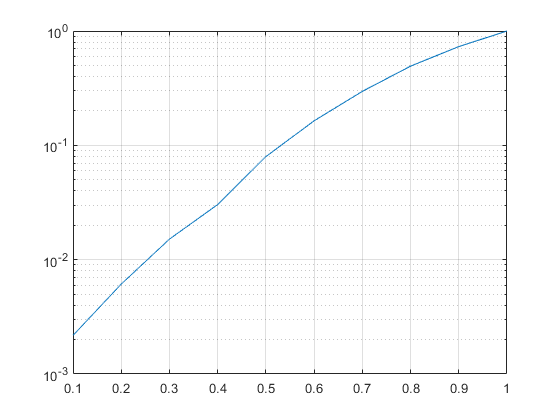


clf
semilogy(x,y)
grid on


slope = mean((y(2:end)-y(1:end-1))./(x(2:end)-x(1:end-1)))

slope = 1.1087

perc = y ./ x

perc =     0.0218    0.0306    0.0504    0.0759    0.1595    0.2732    0.4236    0.6161    0.8119    1.0000


Stability test

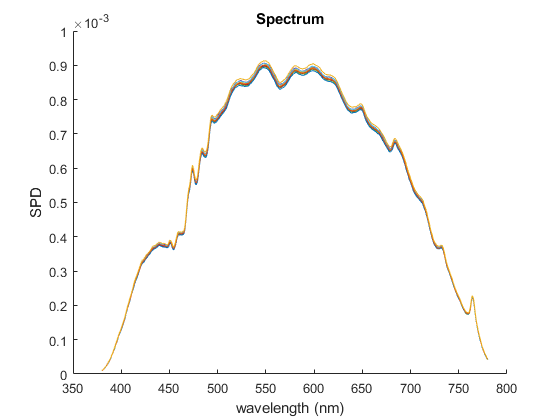

Yxy =    61.0150    0.3781    0.4089


Yxy =    61.2530    0.3780    0.4088


Yxy =    61.3130    0.3778    0.4088


Yxy =    61.6110    0.3779    0.4089


Yxy =    60.9310    0.3780    0.4088


Yxy =    61.5460    0.3779    0.4089


Yxy =    61.1020    0.3780    0.4088


Yxy =    60.6790    0.3780    0.4089


Yxy =    61.1850    0.3779    0.4088


Yxy =    62.0800    0.3779    0.4088



col_range  = [1:1024];
k = 500;
col_range  = [1:(k-1) (k+1):1024];

vec = LightSim.multiple_peaks(col_range);

clf
hold on
for i = 1:10
    ol.setColumn1024(vec)
    mea = cs.measure;
    mea.plot
    spec_stable(i,:) = mea.amplitude';
end

Try subtractive method


col_range  = [1:1024];

vec = LightSim.multiple_peaks(col_range);

ol.setColumn1024(vec)
mea = cs.measure;

Yxy =    61.8130    0.3781    0.4092


spec_measured0 = mea.amplitude';
lum = sum(spec_measured)

Unrecognized function or variable 'spec_measured'.


k = 400
col_range  = [1:(k-1) (k+1):1024];

vec = LightSim.multiple_peaks(col_range);

ol.setColumn1024(vec)
mea = cs.measure;
spec_measured1 = mea.amplitude';
ref_diff = (spec_measured0 - spec_measured1) ./ spec_measured0;

ref1 = spec_measured1 ./ spec_measured0;

%spec_predicted = ls.predict_vec_max(vec,spec_max);

%ratio_all = max(spec_measured) ./ max(spec_predicted)

clf
hold on
%plot(380:780,spec_measured0)
plot(380:780,ref_diff)
plot(380:780,ls.reflectance(k,:))
%plot(380:780,spec_measured0)
%plot(380:780,spec_measured1)
%plot(380:780,spec_predicted)
%legend('measured','predicted')

Check control accuracy


col_range  = [1:1024];

vec = LightSim.multiple_peaks(col_range);

ol.setColumn1024Gamma(vec)
mea = cs.measure;

Yxy =    60.9360    0.3782    0.4093


spec_measured = mea.amplitude';
lum = sum(spec_measured)

lum = 0.2277


spec_predicted = ls.predict_vec_max(vec,spd_max);

ratio_all = max(spec_measured) ./ max(spec_predicted)

ratio_all = 0.9952

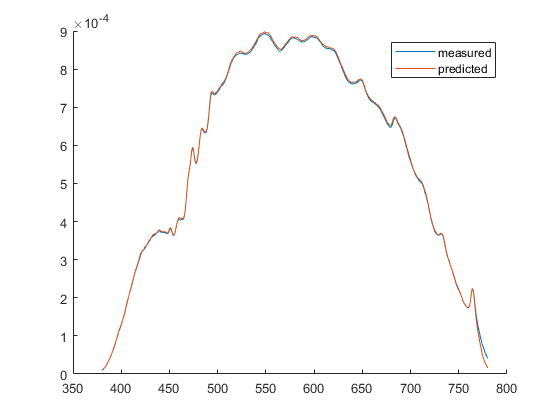


clf
hold on
plot(380:780,spec_measured)
plot(380:780,spec_predicted)
legend('measured','predicted')

light intensity changes over time -- full

spec_predicted = ls.predict_vec_max(LightSim.multiple_peaks([1:1024]),spd_max);

mea = measure_white(ol,cs);

Yxy =    60.6040    0.3782    0.4094


spec_measured = mea.amplitude';

ratio_all = max(spec_measured) ./ max(spec_predicted)

ratio_all = 0.7154

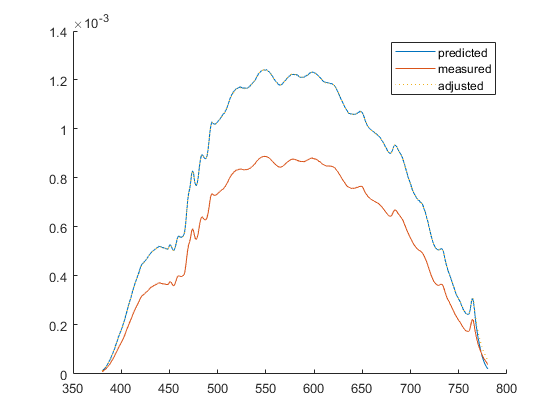


clf
hold on
plot(380:780,spec_predicted)
plot(380:780,spec_measured)
plot(380:780,spec_measured/ratio_all,':')
legend('predicted','measured','adjusted')

Q: why prediction inaccurate?

A: compare prediction and measurement with 8 spikes

vec8_array = ls.vec_8_spikes;
vec8_sum = sum(vec8_array,1);

spec_predicted = ls.predict_vec_max(vec8_sum',spd_max);

ol.setColumn1024(vec8_sum)
mea = cs.measure;

Yxy =    23.4690    0.3846    0.4088


spec_measured = mea.amplitude';

ratio_all = max(spec_measured) ./ max(spec_predicted)

ratio_all = 0.7109

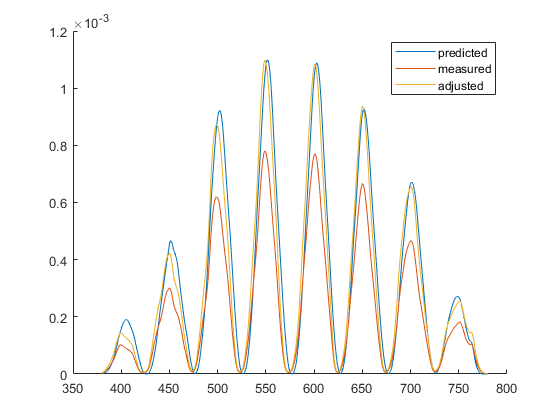


clf
hold on
plot(380:780,spec_predicted)
plot(380:780,spec_measured)
plot(380:780,spec_measured/ratio_all)
legend('predicted','measured','adjusted')

C: there is spectral shifting -- use max(spec) to get amplitude

vec8_array = ls.vec_8_pencils;
vec8_sum = sum(vec8_array,1);

ol.setColumn1024(vec8_sum)
mea = cs.measure;

Yxy =     0.4939    0.3877    0.4106


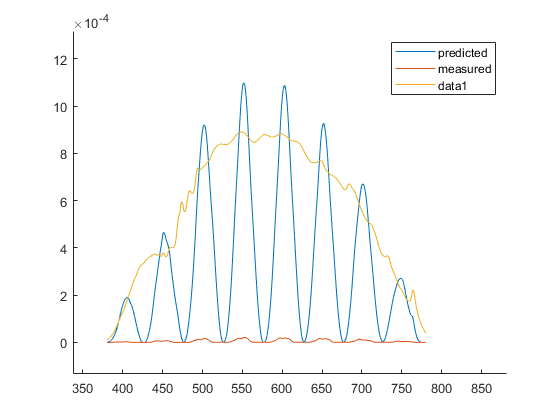

spec_measured = mea.amplitude';

clf
hold on
plot(380:780,spec_predicted)
plot(380:780,spec_measured)
legend('predicted','measured')
plot(380:780,spd_max)

peaks = ls.find_spikes(ls.vec_8_wl,spec_measured);
spike_measured = peaks(:,2);
spike_max = spd_max(peaks(:,1)-380+1);
spike_measured ./ spike_max

ans =     0.0163
    0.0134
    0.0185
    0.0200
    0.0196
    0.0191
    0.0183
    0.0162


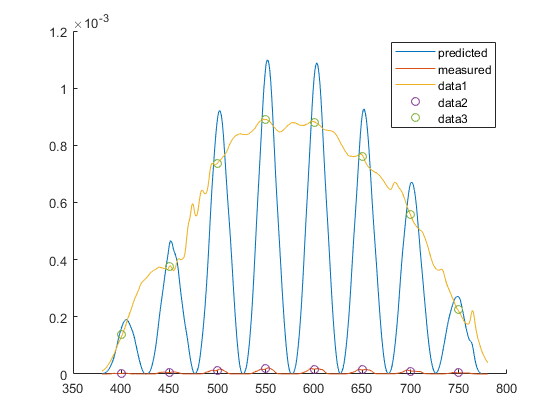

plot(ls.vec_8_wl,spike_measured,'o')
plot(ls.vec_8_wl,spike_max,'o')

Yxy =     0.4897    0.3870    0.4124


Yxy =     0.4889    0.3880    0.4130


Yxy =     0.4875    0.3883    0.4137


Yxy =     0.4866    0.3891    0.4133


Yxy =     0.4861    0.3893    0.4139


Yxy =     0.4867    0.3900    0.4142


Yxy =     0.4860    0.3893    0.4153


Yxy =     0.4859    0.3895    0.4157


Yxy =     0.4859    0.3897    0.4162


Yxy =     0.4864    0.3888    0.4165


Yxy =     0.4846    0.3886    0.4166


Yxy =     0.4867    0.3882    0.4165


Yxy =     0.4861    0.3865    0.4158


Yxy =     0.4874    0.3853    0.4164


Yxy =     0.4876    0.3849    0.4148


Yxy =     0.4908    0.3830    0.4148


Yxy =     0.4895    0.3822    0.4129


Yxy =     0.4916    0.3809    0.4128


Yxy =     0.4939    0.3796    0.4116


Yxy =     0.4941    0.3795    0.4115


Yxy =     0.4936    0.3780    0.4108


Yxy =     0.4951    0.3770    0.4103


Yxy =     0.4961    0.3766    0.4102


Yxy =     0.4958    0.3758    0.4096


Yxy =     0.4957    0.3756    0.4096


Yxy =     0.4958    0.3738    0.4093


Yxy =     0.4948    0.3729    0.4075


Yxy =     0.4954    0.3715    0.4078


Yxy =     0.4953    0.3714    0.4059


Yxy =     0.4962    0.3704    0.4064


Yxy =     0.4941    0.3701    0.4054


Yxy =     0.4927    0.3703    0.4050


Yxy =     0.4931    0.3709    0.4053


Yxy =     0.4914    0.3715    0.4054


Yxy =     0.4907    0.3728    0.4042


Yxy =     0.4905    0.3728    0.4039


Yxy =     0.4891    0.3738    0.4046


Yxy =     0.4901    0.3745    0.4048


Yxy =     0.4886    0.3757    0.4039


Yxy =     0.4892    0.3771    0.4049


Yxy =     0.4883    0.3775    0.4049


Yxy =     0.4882    0.3784    0.4054


Yxy =     0.4886    0.3797    0.4059


Yxy =     0.4891    0.3808    0.4063


Yxy =     0.4885    0.3822    0.4075


Yxy =     0.4875    0.3826    0.4078


Yxy =     0.4894    0.3840    0.4093


Yxy =     0.4886    0.3846    0.4102


Yxy =     0.4889    0.3857    0.4109


Yxy =     0.4865    0.3869    0.4120


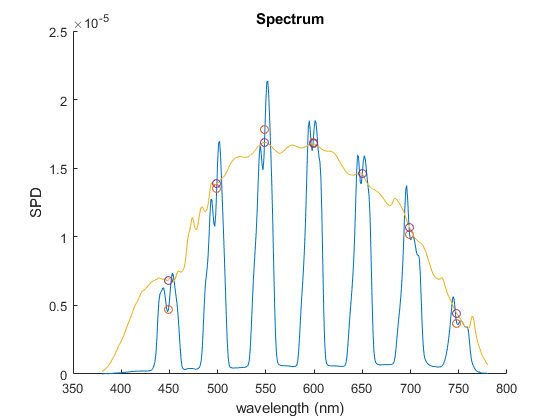

for i = 1:50
    wl_range = [400+(i-1)*1:50:750];
    mea = measure_8_spikes(ol,cs,wl_range);
    peaks = ls.find_spikes(wl_range,mea.amplitude);
    spike_wl = peaks(:,1);
    spike_measured = peaks(:,2);
    spike_max = spd_max(spike_wl-380+1);
    spike_data{i} = spike_measured ./ spike_max;
    clf
    hold on
    mea.plot
    plot(spike_wl,spike_measured,'o')
    plot(380:780,spd_max*0.02)
    plot(spike_wl,spike_max*0.02,'o')
end

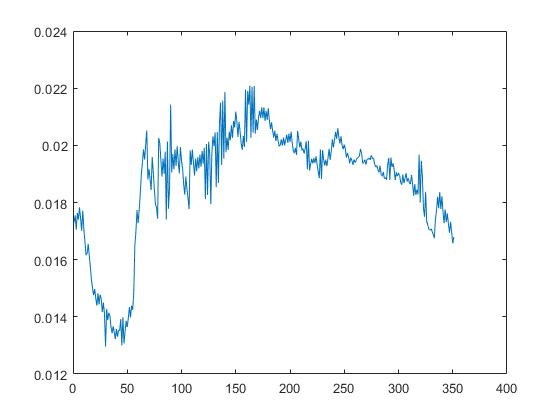

rr = zeros(750,1);
for i = 1:50
    rr(400+(i-1)*1:50:750) = spike_data{i};
end
rrr = rr(400:1:750);
clf
plot(rrr)

function mea = measure_white (ol,cs)
c_range = 1:1024;
vec = LightSim.multiple_peaks(c_range);
ol.setColumn1024(vec)
mea = cs.measure;
end

function mea = measure_black (ol,cs)
c_range = [];
vec = LightSim.multiple_peaks(c_range);
ol.setColumn1024(vec)
mea = cs.measure;
end

function mea = measure_8_spikes (ol,cs,wl_range)
load('column_transparency.mat','col_wl')
col_range = round(interp1(col_wl(:,2),col_wl(:,1),wl_range,'spline','extrap'));
col_range = min(col_range,1024);
col_range = max(col_range,1);
vec = LightSim.multiple_peaks(col_range);
ol.setColumn1024(vec)
mea = cs.measure;
end